Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2)+sin(24*x-4);

xx = lhsdesign(200,1);
yy = f1(xx);

x1 = lhsdesign(1000,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.2);

ma = means.sine(1,24,0,1) + means.const(2) + means.linear(6);
a = kernels.Matern52(1,0.2) + kernels.EQ(1,0.2);

a.signn = 0.5;

Z = VGP(ma,a,lhsdesign(5,1));

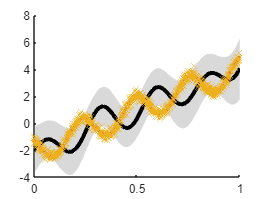

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
utils.plotLineOut(Z1,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')

tic
[Z2,LL] = Z1.train(1);
toc

Elapsed time is 4.301654 seconds.


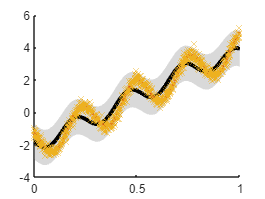

figure
hold on
utils.plotLineOut(Z2,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')


opts = bads('Defaults');
opts.Display = 'final';

for i = 1:10
    xn = bads(@(x) Z2.newXuDiff(x),rand(1),0,1,0,1,[],opts);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -0.035447.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -0.0196336.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -0.00582308.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -17.7176.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -60.5104.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value le

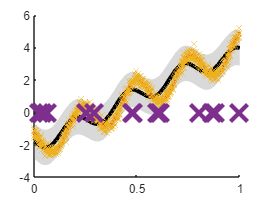


figure
hold on
utils.plotLineOut(Z2,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train(1);
toc

Elapsed time is 8.348367 seconds.


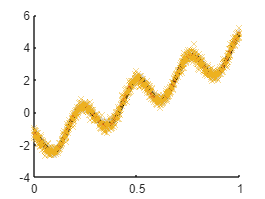


[ys,sig] = Z3.eval(xx);

figure
hold on
utils.plotLineOut(Z3,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')